## Import

clear all; close all;
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
img = imread(fullfile(fileparts(mfilePath), 'test_img.png'));
% You can use this blank image for drawing
% img = ones(1000);

## Domain

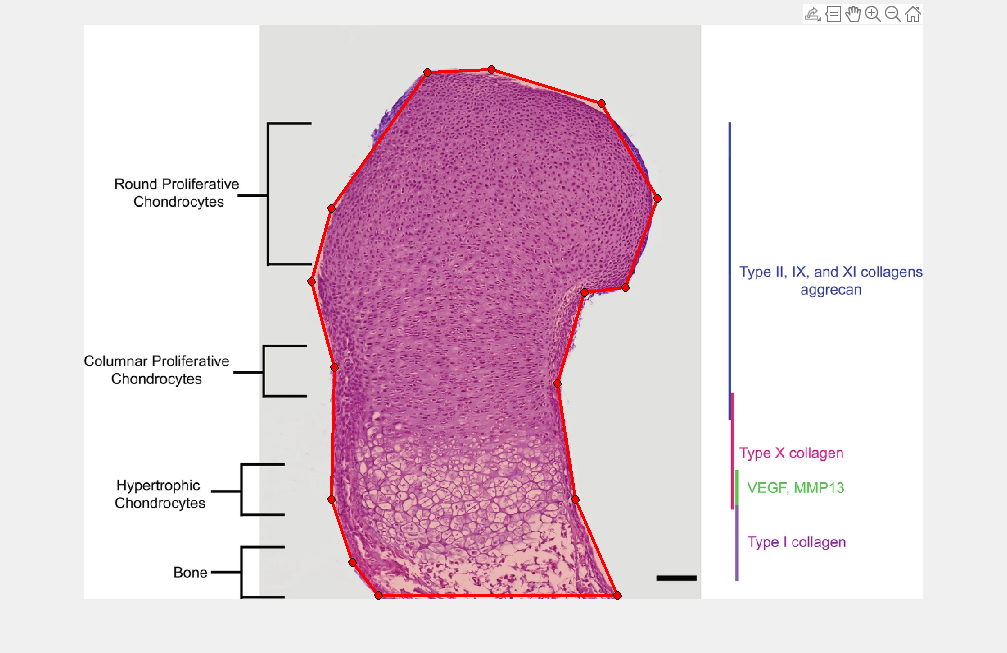

% Remember to draw points in clockwise fashion
imshow(img);
roi = drawpolygon('Color','r');

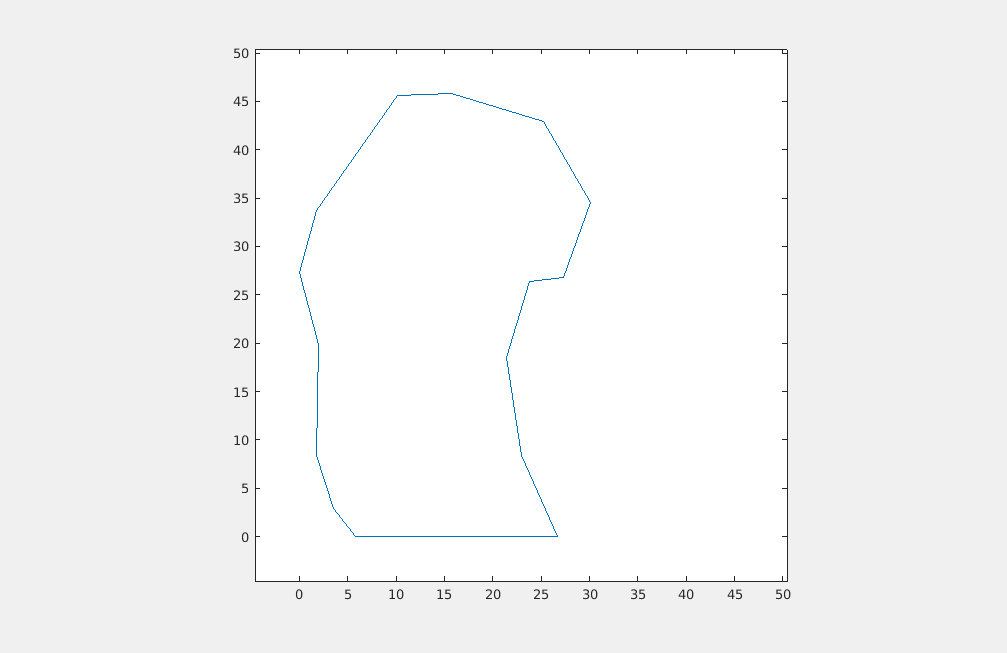

% Enter the expected number of cells at confluency
expect_n = 20;
%
coords = roi.Position;
left_D = min(coords(:, 1));
top_D = max(coords(:, 2));
divisor_D = max(coords(:));
coords_normalized = pixel_coordinate_normalization(coords, top_D, left_D, divisor_D);
a_normalized = polyarea(coords_normalized(:, 1), coords_normalized(:, 2));
ss = expect_n / a_normalized;
coords = coords_normalized * ss;
v_ns_D = domain_normal_vectors(coords);
v_ts_D = domain_tangent_vectors(coords);

plot(cat(1, coords(:, 1), coords(1, 1)), cat(1, coords(:, 2), coords(1, 2)));
pbaspect([1 1 1]);
xlim([-0.1 * max(coords(:)), 1.1 * max(coords(:))]);
ylim([-0.1 * max(coords(:)), 1.1 * max(coords(:))]);

## Interface

v_n =     0.5572
    0.8304


v_n =    -0.0152
    0.9999


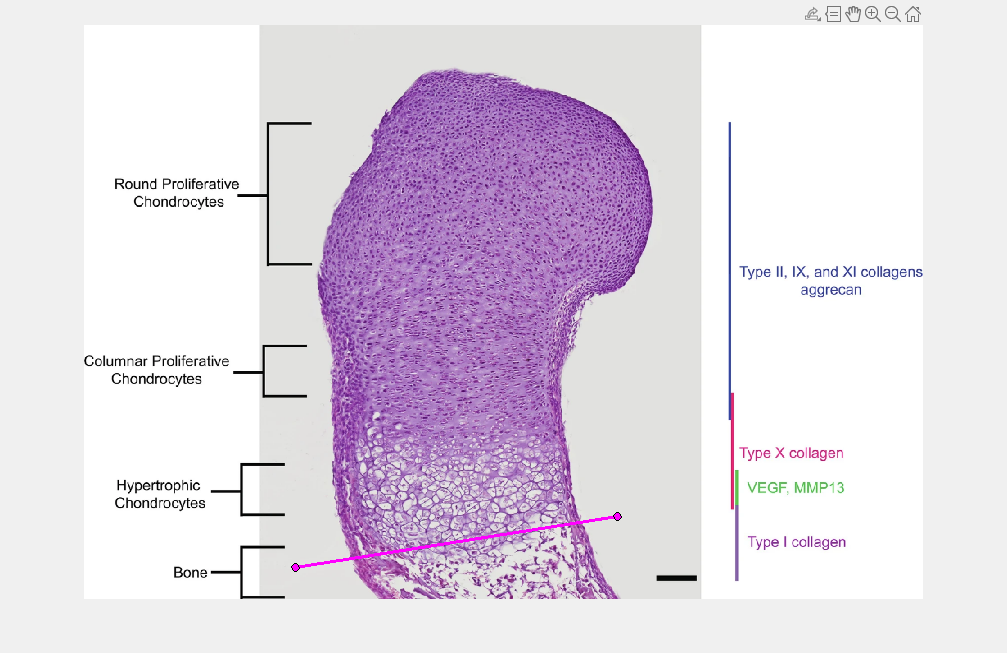

v_n =    -0.1564
    0.9877


num_of_interfaces = 3;
i_ps_full = cell(1, num_of_interfaces);
v_ns = zeros([3, 2]);
% After drawing, hit enter to goto the next interface specification
for i = 1:num_of_interfaces
    % Specify interfaces in proximal(cartilage cap)-distal(bone center) direction.
    imshow(img);
    loi = drawline('Color','magenta');
    pause;
    coords_interface = loi.Position;
    coords_normalized = pixel_coordinate_normalization(coords_interface, top_D, left_D, divisor_D);
    coords_interface = coords_normalized * ss;
    [xi, yi] = polyxpoly(coords_interface(:, 1), coords_interface(:, 2), coords(:, 1), coords(:, 2));
    v_t = (coords_interface(1, :) - coords_interface(2, :)) / norm(coords_interface(1, :) - coords_interface(2, :));
    % This is a simple determination of the direction of
    % normal vector of the interface. If the final domain
    % is wrong, set normal vector manually so that it points
    % into the region of interest (e.g. resting zone)
    if v_t(1) >= 0
        v_n = [-v_t(2); v_t(1)]
    elseif v_t(1) < 0
        v_n = [v_t(2); -v_t(1)]
    end
    i_ps_full{i} = cat(2, xi, yi);
    v_ns(i, :) = v_n;
end

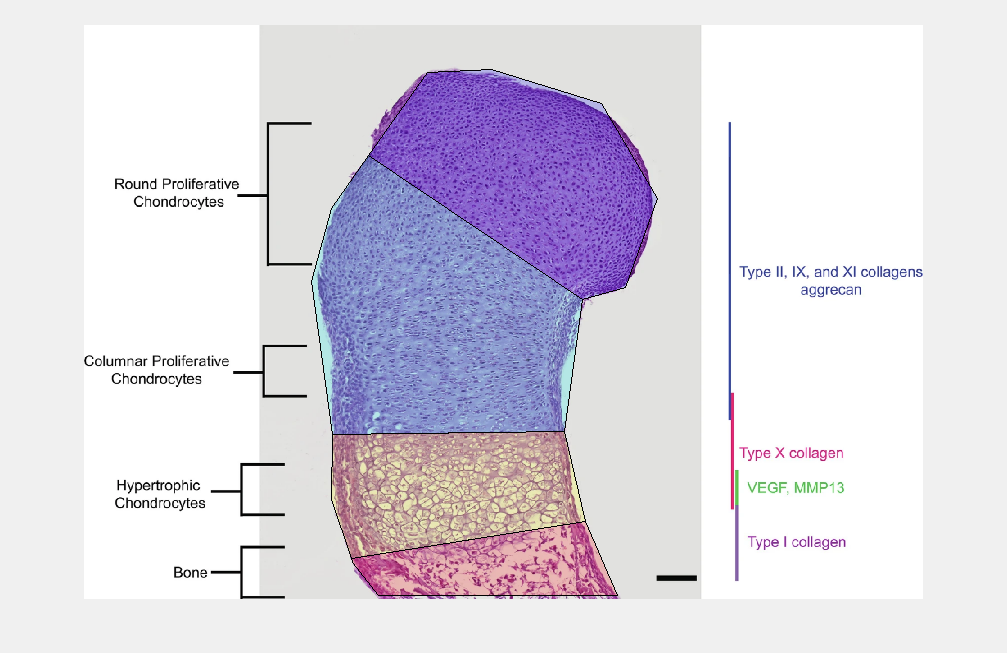

i_ps = cellfun(@(x) x(1, :), i_ps_full, 'UniformOutput', false);
sub_domains = find_subdomain(v_ns, i_ps, coords, i_ps_full);

% If not satisfied, rerun the block
colors = jet(num_of_interfaces + 1);
imshow(img);
coord_D = back2pixel_coord(coords, top_D, left_D, divisor_D, ss);
%patch(coord_D(:, 1), coord_D(:, 2), "black", 'FaceAlpha', 0.1);
for i = 1:(num_of_interfaces + 1)
    sub_domains_coords = back2pixel_coord(sub_domains{i}, top_D, left_D, divisor_D, ss);
    patch(sub_domains_coords(:, 1), sub_domains_coords(:, 2), colors(i, :), 'FaceAlpha', 0.2);
end

## Export

mkdir(fullfile(fileparts(mfilePath), 'cartilage/initial'));
mkdir(fullfile(fileparts(mfilePath), 'cartilage/output'));
writematrix(coords, fullfile(fileparts(mfilePath), 'cartilage/initial/domain_coords.txt'));
writematrix(v_ns_D, fullfile(fileparts(mfilePath), 'cartilage/initial/domain_v_ns.txt'));
writematrix(v_ts_D, fullfile(fileparts(mfilePath), 'cartilage/initial/domain_v_ts.txt'));
writematrix(cell2mat(i_ps_full), fullfile(fileparts(mfilePath), 'cartilage/initial/interface_coords.txt'));
writematrix(v_ns, fullfile(fileparts(mfilePath), 'cartilage/initial/interface_v_ns.txt'));

## Visualization

last_time = 1;
output_folder = fullfile(fileparts(mfilePath), "cartilage/output/");

### Live

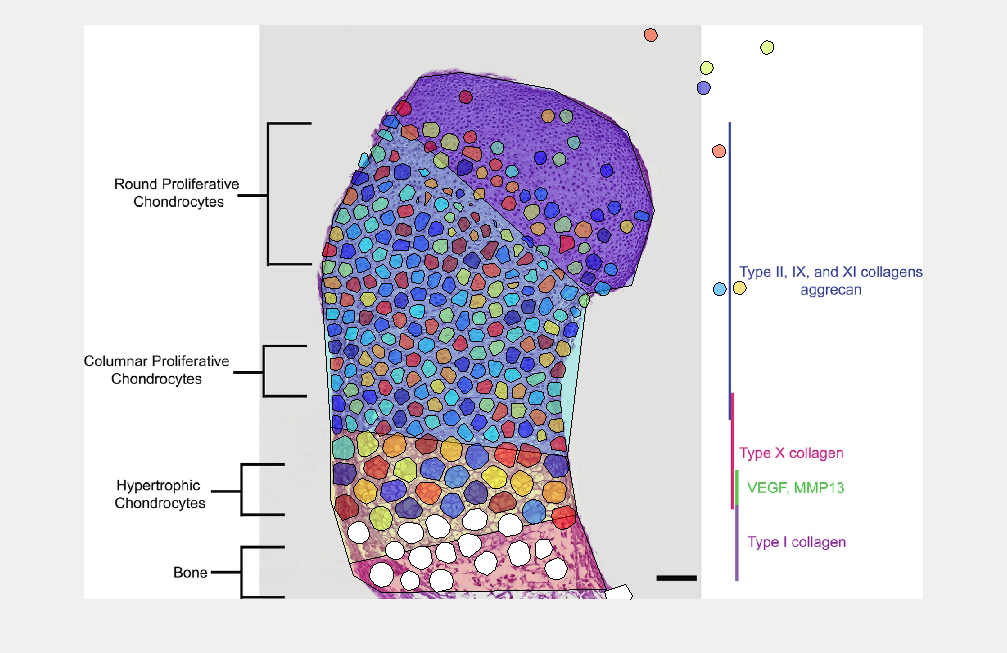

f = figure;
set(gcf,'Visible','on');
ax = axes('Parent', f, 'position', [0.13 0.39  0.77 0.54]);
while true
    pause(5);
    if (~isfile(fullfile(fileparts(mfilePath), sprintf('cartilage/output/X_%d.txt', last_time))))
       continue
    end
    t = last_time;
    last_time = last_time + 1;

    values_XC_pre = dictionary;
    values_YC_pre = dictionary;
        
    fid_X = fopen(fullfile(output_folder, sprintf("X_%d.txt", t)));
    fid_Y = fopen(fullfile(output_folder, sprintf("Y_%d.txt", t)));
    % is XS and YS flipped?
    fid_YS = fopen(fullfile(output_folder, sprintf("XS_%d.txt", t)));
    fid_XS = fopen(fullfile(output_folder, sprintf("YS_%d.txt", t)));

    fid_YC = fopen(fullfile(output_folder, sprintf("YC_%d.txt", t)));
    fid_XC = fopen(fullfile(output_folder, sprintf("XC_%d.txt", t)));

    fid_live = fopen(fullfile(output_folder, sprintf("C_dead_%d.txt", t)));
    nline_X = fgetl(fid_X);
    nline_Y = fgetl(fid_Y);
    nline_XS = fgetl(fid_XS);
    nline_YS = fgetl(fid_YS);
    nline_XC = fgetl(fid_XC);
    nline_YC = fgetl(fid_YC);
    nline_live = fgetl(fid_live);
    
    poly_collections_cells = {};
    poly_collections_shoulders = {};
    centroids = dictionary;
    live_or_not = dictionary;
    slope_field = [];
    n_poly = 0;
    while ischar(nline_X)
        values_X = str2double(strsplit(nline_X));
        values_Y = str2double(strsplit(nline_Y));
        values_XS = str2double(strsplit(nline_XS));
        values_YS = str2double(strsplit(nline_YS));
        values_live = str2double(strsplit(nline_live));
        values_XC = str2double(strsplit(nline_XC));
        values_YC = str2double(strsplit(nline_YC));
        centroids(int2str(values_XC(1))) = {[values_XC(2); values_YC(2)]};
        live_or_not(int2str(values_live(1))) = values_live(2);

        n_poly = n_poly + 1;
        % last value is NaN
        poly_collections_cells{end + 1} = {values_X(1), cat(1, values_X(2:(end - 1)), values_Y(2:(end - 1)))};
        poly_collections_shoulders{end + 1} = {values_XS(1), cat(1, values_XS(2:(end - 1)), values_YS(2:(end - 1)))};
        nline_X = fgetl(fid_X);
        nline_Y = fgetl(fid_Y);
        nline_XS = fgetl(fid_XS);
        nline_YS = fgetl(fid_YS);
        nline_XC = fgetl(fid_XC);
        nline_YC = fgetl(fid_YC);
        nline_live = fgetl(fid_live);
        out = {n_poly, poly_collections_cells, poly_collections_shoulders, centroids, slope_field, live_or_not};
    end
    clf;
    colors_domain = jet(num_of_interfaces + 1);
    imshow(img);
    for i = 1:(num_of_interfaces + 1)
        sub_domains_coords = back2pixel_coord(sub_domains{i}, top_D, left_D, divisor_D, ss);
        patch(sub_domains_coords(:, 1), sub_domains_coords(:, 2), colors_domain(i, :), 'FaceAlpha', 0.2);
    end
    polygons = out;
    n_polygons = polygons{1};
    live_status = polygons{6};
    n_colors = 20;
    colors = jet(n_colors);
    centorids = reshape(cell2mat(values(polygons{4})), 2, []);
    live_status_vec = values(live_status);
    ignored_cells = [];
    for i = 1:n_polygons
        % cell
        xy_origin = polygons{2}{i}{2};
        nonzero = xy_origin(1, :) ~= 0 & xy_origin(2, :) ~= 0;
        xy = back2pixel_coord(polygons{2}{i}{2}', top_D, left_D, divisor_D, ss);

        xx = xy(:, 1); 
        yy = xy(:, 2);
        if ~ismember(i, ignored_cells)
            if live_status_vec(i) == 0
                patch(xx(nonzero), yy(nonzero), colors(mod(i, n_colors) + 1, :), 'FaceAlpha', 0.5);
            elseif live_status_vec(i) == 1
                patch(xx(nonzero), yy(nonzero), 'white', 'FaceAlpha', 1);
            end
        end
    end
end

### Full history and flow

time_range = 1:(last_time - 1);
values_XC_pre = dictionary;
values_YC_pre = dictionary;
for t = time_range
    fid_X = fopen(fullfile(output_folder, sprintf("X_%d.txt", t)));
    fid_Y = fopen(fullfile(output_folder, sprintf("Y_%d.txt", t)));
    % is XS and YS flipped?
    fid_YS = fopen(fullfile(output_folder, sprintf("XS_%d.txt", t)));
    fid_XS = fopen(fullfile(output_folder, sprintf("YS_%d.txt", t)));

    fid_YC = fopen(fullfile(output_folder, sprintf("YC_%d.txt", t)));
    fid_XC = fopen(fullfile(output_folder, sprintf("XC_%d.txt", t)));

    fid_live = fopen(fullfile(output_folder, sprintf("C_dead_%d.txt", t)));
    nline_X = fgetl(fid_X);
    nline_Y = fgetl(fid_Y);
    nline_XS = fgetl(fid_XS);
    nline_YS = fgetl(fid_YS);
    nline_XC = fgetl(fid_XC);
    nline_YC = fgetl(fid_YC);
    nline_live = fgetl(fid_live);
    
    poly_collections_cells = {};
    poly_collections_shoulders = {};
    centroids = dictionary;
    slope_field = dictionary;
    live_or_not = dictionary;
    n_poly = 0;
    while ischar(nline_X)
        values_X = str2double(strsplit(nline_X));
        values_Y = str2double(strsplit(nline_Y));
        values_XS = str2double(strsplit(nline_XS));
        values_YS = str2double(strsplit(nline_YS));
        values_live = str2double(strsplit(nline_live));

        if t > 1
            values_XC = str2double(strsplit(nline_XC));
            values_YC = str2double(strsplit(nline_YC));
            if isKey(values_XC_pre, int2str(values_XC(1)))
                centroid_X_pre = values_XC_pre(int2str(values_XC(1)));
                centroid_Y_pre = values_YC_pre(int2str(values_YC(1)));
                centroid_X_current = values_XC(2);
                centroid_Y_current = values_YC(2);
                slope_field(int2str(values_XC(1))) = {[centroid_X_current - centroid_X_pre; centroid_Y_current - centroid_Y_pre]};
            end
        else
            values_XC = str2double(strsplit(nline_XC));
            values_YC = str2double(strsplit(nline_YC));
        end

        centroids(int2str(values_XC(1))) = {[values_XC(2); values_YC(2)]};
        live_or_not(int2str(values_live(1))) = values_live(2);

        n_poly = n_poly + 1;
        % last value is NaN
        poly_collections_cells{end + 1} = {values_X(1), cat(1, values_X(2:(end - 1)), values_Y(2:(end - 1)))};
        poly_collections_shoulders{end + 1} = {values_XS(1), cat(1, values_XS(2:(end - 1)), values_YS(2:(end - 1)))};
        nline_X = fgetl(fid_X);
        nline_Y = fgetl(fid_Y);
        nline_XS = fgetl(fid_XS);
        nline_YS = fgetl(fid_YS);
        nline_XC = fgetl(fid_XC);
        nline_YC = fgetl(fid_YC);
        nline_live = fgetl(fid_live);
        values_XC_pre(int2str(values_XC(1))) = values_XC(2);
        values_YC_pre(int2str(values_YC(1))) = values_YC(2);
    end
    out{t} = {n_poly, poly_collections_cells, poly_collections_shoulders, centroids, slope_field, live_or_not};
end
last_time_step = last_time - 1;
flow = dictionary;
for i = 1:out{last_time_step}{1}
   flow(int2str(i)) = {[]};
   for j = 1:last_time_step
      if isKey(out{j}{4}, int2str(i))
        flow(int2str(i)) = {cat(1, flow{int2str(i)}, out{j}{4}{int2str(i)}')};
      end
   end
end

### Flow

n_colors = 20;
colors = jet(n_colors);
f = figure;
set(gcf,'Visible','on');
colors_domain = jet(num_of_interfaces + 1);
imshow(img);
for i = 1:(num_of_interfaces + 1)
    sub_domains_coords = back2pixel_coord(sub_domains{i}, top_D, left_D, divisor_D, ss);
    patch(sub_domains_coords(:, 1), sub_domains_coords(:, 2), colors_domain(i, :), 'FaceAlpha', 0.2);
end
hold on
for i = 1:out{last_time_step}{1}
    xy = back2pixel_coord(flow{int2str(i)}, top_D, left_D, divisor_D, ss);
    plot(xy(:, 1), xy(:, 2), 'color', colors(mod(i, n_colors) + 1, :));
    hold on
    plot(xy(end, 1), xy(end, 2), '-*', 'color', colors(mod(i, n_colors) + 1, :));
    hold on
end
exportgraphics(f, 'flow.png', 'Resolution', 500);

### GIF

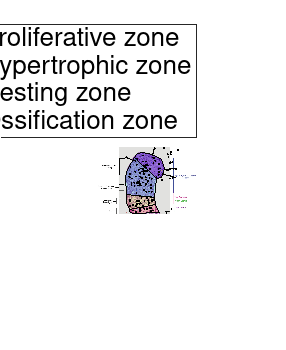

lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4375 0.8561 0.1551 0.0486]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


lgd =   Legend (Proliferative zone, Hypertrophic zone, Resting zone, Ossification zone) with properties:

         String: {'Proliferative zone'  'Hypertrophic zone'  'Resting zone'  'Ossification zone'}
       Location: 'northoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4203 0.8615 0.1595 0.1003]
          Units: 'normalized'

  Show all properties


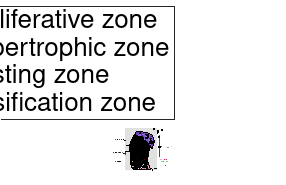

if isfile(fullfile(fileparts(mfilePath), 'cartilage_simulation.gif'))
    delete(fullfile(fileparts(mfilePath), 'cartilage_simulation.gif'));
end
last_time_step = last_time - 1;
%time_step =96;
f = figure;
set(gcf,'Position',[100 100 900 1100]);
ax = axes('Parent', f, 'position', [0.13 0.39  0.77 0.54]);
colors_domain = jet(num_of_interfaces + 1);
for time_step = 1:last_time_step
    polygons = out{time_step};
    n_polygons = polygons{1};
    live_status = polygons{6};
    live_status_vec = values(live_status);
    %n_colors = min(20, n_polygons);
    n_colors = 20;
    colors = jet(n_colors);
    imshow(img);
    for i = 1:(num_of_interfaces + 1)
        sub_domains_coords = back2pixel_coord(sub_domains{i}, top_D, left_D, divisor_D, ss);
        patch(sub_domains_coords(:, 1), sub_domains_coords(:, 2), colors_domain(i, :), 'FaceAlpha', 0.2);
    end
    ignored_cells = [];
    for i = 1:n_polygons
        xy_origin = polygons{2}{i}{2};
        nonzero = xy_origin(1, :) ~= 0 & xy_origin(2, :) ~= 0;
        xy = back2pixel_coord(polygons{2}{i}{2}', top_D, left_D, divisor_D, ss);

        xx = xy(:, 1); 
        yy = xy(:, 2);

        if ~ismember(i, ignored_cells)
            if live_status_vec(i) == 0
                patch(xx(nonzero), yy(nonzero), colors(mod(i, n_colors) + 1, :), 'FaceAlpha', 0.5);
            elseif live_status_vec(i) == 1
                patch(xx(nonzero), yy(nonzero), 'white', 'FaceAlpha', 1);
            end
        end
    end
    hold on
    lgd = legend([patch(NaN, NaN, "yellow", 'FaceAlpha', 0.1) patch(NaN, NaN, "green", 'FaceAlpha', 0.1) patch(NaN, NaN, "black", 'FaceAlpha', 0.1), patch(NaN, NaN, "magenta", 'FaceAlpha', 0.1)], ["Proliferative zone", "Hypertrophic zone", "Resting zone", "Ossification zone"], "Location", "northoutside")
    fontsize(lgd, 20, 'points');
    drawnow
    exportgraphics(gcf, fullfile(fileparts(mfilePath), 'cartilage_simulation.gif'),'Append',true, 'Resolution', 300);
    frame = getframe(f);
    im{time_step} = frame2im(frame);
    clf
end

function coords_normalized = pixel_coordinate_normalization(coords, top, left, divisor)
    yy = coords(:, 2);
    xx = coords(:, 1);
    yy_normalized = (top - yy) / divisor;
    xx_normalized = (xx - left) / divisor;
    coords_normalized = cat(2, xx_normalized, yy_normalized);
end

function pixel_coord = back2pixel_coord(coords, top, left, divisor, ss)
    yy = coords(:, 2) / ss;
    xx = coords(:, 1) / ss;
    yy_pixel = top - divisor * yy;
    xx_pixel = left + divisor * xx;
    pixel_coord = cat(2, xx_pixel, yy_pixel);
end

function v_ns = domain_normal_vectors(coords)
    v_ns = zeros(size(coords, 1), 2);
    for i = 1:size(coords, 1)
        p_current = coords(i, :);
        if i == size(coords, 1)
            p_next = coords(1, :);
        else
            p_next = coords(i + 1, :);
        end
        v_t = (p_next - p_current) / norm(p_next - p_current);
        % v_n points into the domain
        v_n = [-v_t(2) v_t(1)];
        v_ns(i, :) = v_n;
    end
end

function v_ts = domain_tangent_vectors(coords)
    v_ts = zeros(size(coords, 1), 2);
    for i = 1:size(coords, 1)
        p_current = coords(i, :);
        if i == size(coords, 1)
            p_next = coords(1, :);
        else
            p_next = coords(i + 1, :);
        end
        v_t = (p_next - p_current) / norm(p_next - p_current);
        v_ts(i, :) = v_t;
    end
end

function sub_polys = find_subdomain(v_ns, i_ps, poly, i_ps_full, a)
    sub_polys = cell(1, size(i_ps, 2) + 1);
    sub_polys(:) = {[]};
    for i = 1:size(sub_polys, 2)
        if i == 1
            sub_polys(i) = {cat(1, sub_polys{i}, i_ps_full{i})};
        elseif i == size(sub_polys, 2)
            sub_polys(i) = {cat(1, sub_polys{i}, i_ps_full{i - 1})};
        else
            sub_polys(i) = {cat(1, sub_polys{i}, i_ps_full{i - 1}, i_ps_full{i})};
        end
    end
    for i = 1:size(poly, 1)
        p_poly = poly(i, :);
        min_dist = Inf;
        final_subdomain = -1;
        for j = 1:size(i_ps, 2)
            dist = dot((p_poly - i_ps{j}), v_ns(j, :));
            if dist >= 0
                if dist < min_dist
                    min_dist = dist;
                    final_subdomain = j;
                end
            end
        end
        % All bottom points belong to bottom region
        if final_subdomain == -1
            sub_polys(end) = {cat(1, sub_polys{end}, p_poly)};
        else
            sub_polys(final_subdomain) = {cat(1, sub_polys{final_subdomain}, p_poly)};
        end
    end
    for i = 1:size(sub_polys, 2)
        reorder_index = convhull(sub_polys{i});
        sub_polys{i} = sub_polys{i}(reorder_index, :);
    end
end